# NTC ahora ln

## With 3 values

%Datos obtenidos
A = [30.5 44.0 57.0    70.0   83.7   101.7];
A = A + 273.15;
B = [9.35e3 5.13e3 3e3 1.82e3 1.12e3 619];
AA = [9.7 14.8 15.3 21.2 25.1 29.5];
AA = AA + 273.15;
BB = [27.9e3 20.6e3 20e3 15.05e3 12.6e3 10e3];

xData = [AA A]

xData =   282.8500  287.9500  288.4500  294.3500  298.2500  302.6500  303.6500  317.1500  330.1500  343.1500  356.8500  374.8500


yData = [BB B]

yData =        27900       20600       20000       15050       12600       10000        9350        5130        3000        1820        1120         619


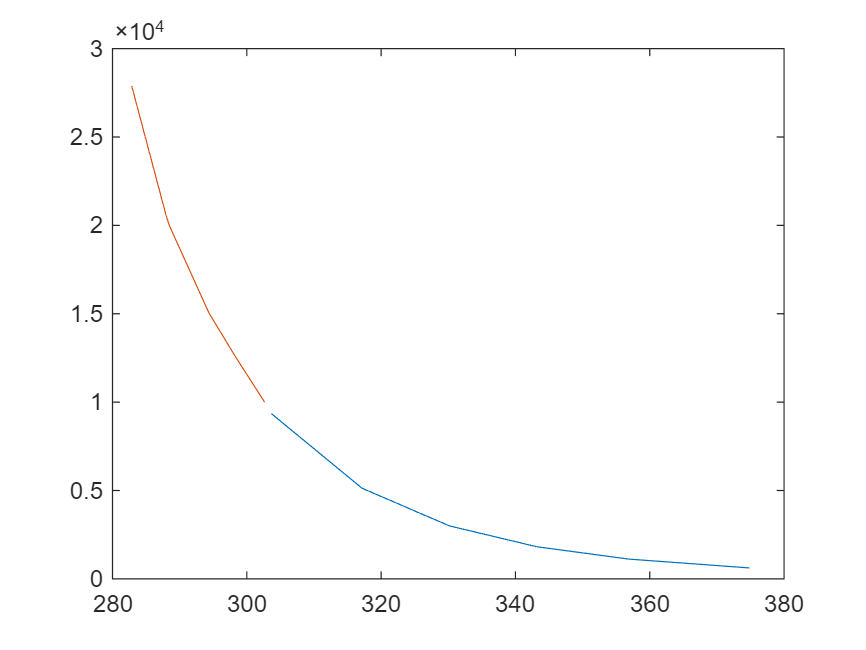


plot(A, B , AA ,BB)


% Determinando parámetros 
syms aplus bplus cplus
T1p = AA(1) == (aplus + bplus*log(BB(1)) + cplus*log(BB(1))^3 )^-1

$$T1p = \frac{5657}{20}=\frac{1}{\mathrm{aplus}+\frac{1440642687995273\,\mathrm{bplus}}{140737488355328}+\frac{1179340670676481\,\mathrm{cplus}}{1099511627776}}$$

T3p = A(3) ==  (aplus + bplus*log(B(3))  + cplus*log(B(3))^3 )^-1

$$T3p = \frac{6603}{20}=\frac{1}{\mathrm{aplus}+\frac{4507184249282609\,\mathrm{bplus}}{562949953421312}+\frac{1128590513718437\,\mathrm{cplus}}{2199023255552}}$$

T6p = A(6) ==  (aplus + bplus*log(B(6))  + cplus*log(B(6))^3 )^-1

$$T6p = \frac{7497}{20}=\frac{1}{\mathrm{aplus}+\frac{7237403127690167\,\mathrm{bplus}}{1125899906842624}+\frac{4672709165512927\,\mathrm{cplus}}{17592186044416}}$$


% 1p 3 6
sol5 = solve([T1p,T3p,T6p],[aplus,bplus,cplus]);
aplus = vpa(sol5.aplus)

$$aplus = 0.001183044463397467489884575310446$$

bplus = vpa(sol5.bplus)

$$bplus = 0.00023172422193125217298755289696206$$

cplus = vpa(sol5.cplus)

$$cplus = -0.000000018291274684676256209602765682178$$

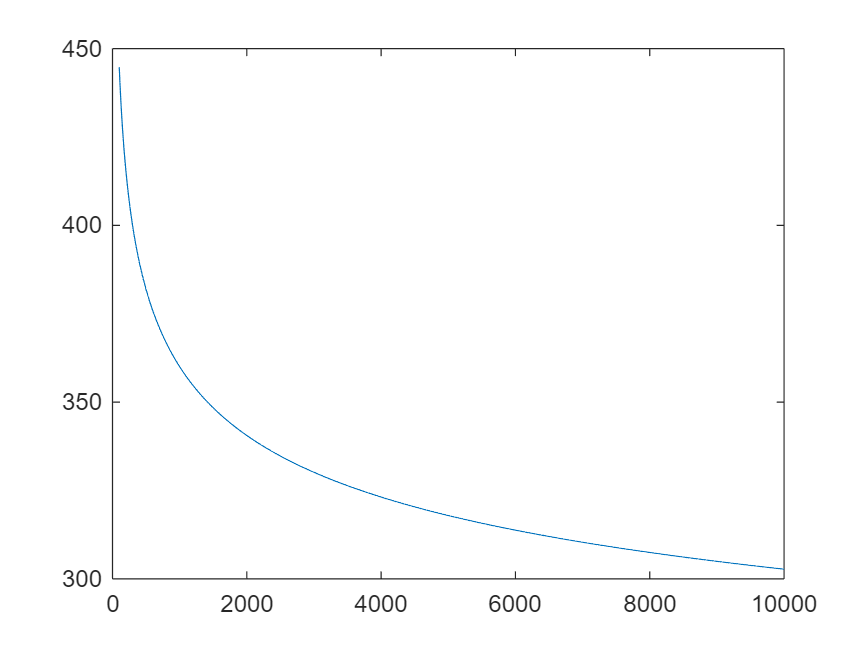


%Grafico ecuacion
x = linspace(100,10000,1000);
SH_1p36= (aplus  + bplus.*log(x) + cplus.*log(x).^3 ).^-1;
plot(x,SH_1p36)


%Valor de muestra
r1 = 10000;
SH_1p36 = (aplus + bplus.*log(r1)+ cplus.*log(r1).^3 ).^-1

$$SH\_1p36 = 302.75395805730784439716920637111$$


SH_1p36 - 273.15

$$ans = 29.603958057307844397169206371112$$

## With all values

% --- 1. Data Definition ---
xData = [282.85, 287.95, 288.45, 294.35, 298.25, 302.65, 303.65, 317.15, 330.15, 343.15, 356.85, 374.85];
yData = [27900, 20600, 20000, 15050, 12600, 10000, 9350, 5130, 3000, 1820, 1120, 619];

% --- 2. Data Transformation ---
% The model fits the inverse of xData using a function of log(yData).
yData_log = log(yData);   % Independent variable (input to the fit)
xData_inv = 1 ./ xData;     % Dependent target (output of the fit)

% --- 3. Model Function Definition ---
% The function models the relationship: 1/x = z(1) + z(2)*log(y) + z(3)*log(y)^3
fun_poly = @(z, yData_log) z(1) + z(2) * yData_log + z(3) * yData_log.^3;

% --- 4. Solver Setup and Fit ---
% Initial guess for the parameters [z1, z2, z3]
z0 = [1e-3, 1e-3, 1e-6]; 
options = optimoptions('lsqcurvefit', ...
    'Algorithm', 'levenberg-marquardt', ...  
    'MaxIterations', 1000, ...               
    'Display', 'final'); 

% Execute the fit: fitting z to model xData_inv based on yData_log
[z_fit, resnorm, residual, exitflag, output] = lsqcurvefit(fun_poly, z0, yData_log, xData_inv, [], [], options);


Local minimum found.

Optimization completed because the size of the gradient is less than
1e-4 times the value of the function tolerance.

<stopping criteria details>


disp(['Exit Flag: ', num2str(exitflag)]);

Exit Flag: 1


vpa([z_fit(1) z_fit(2) z_fit(3)]')

$$ans = \left(\begin{array}{c} 0.0011783191977698312651740009115997\\ 0.00023216671014162360551537356290197\\ -0.000000014937998019228263835830311100257 \end{array}\right)$$

% --- 5. Goodness of Fit (R-squared) ---
y_target = xData_inv;
y_mean = mean(y_target);

SS_res = resnorm; % Sum of Squares of Residuals (from lsqcurvefit output)
SS_tot = sum((y_target - y_mean).^2); % Total Sum of Squares

R_squared = 1 - (SS_res / SS_tot);
R = sqrt(R_squared);

disp(['R-squared (R^2): ', num2str(R_squared)]);

R-squared (R^2): 0.99992


disp(['Correlation Coefficient (R): ', num2str(R)]);

Correlation Coefficient (R): 0.99996


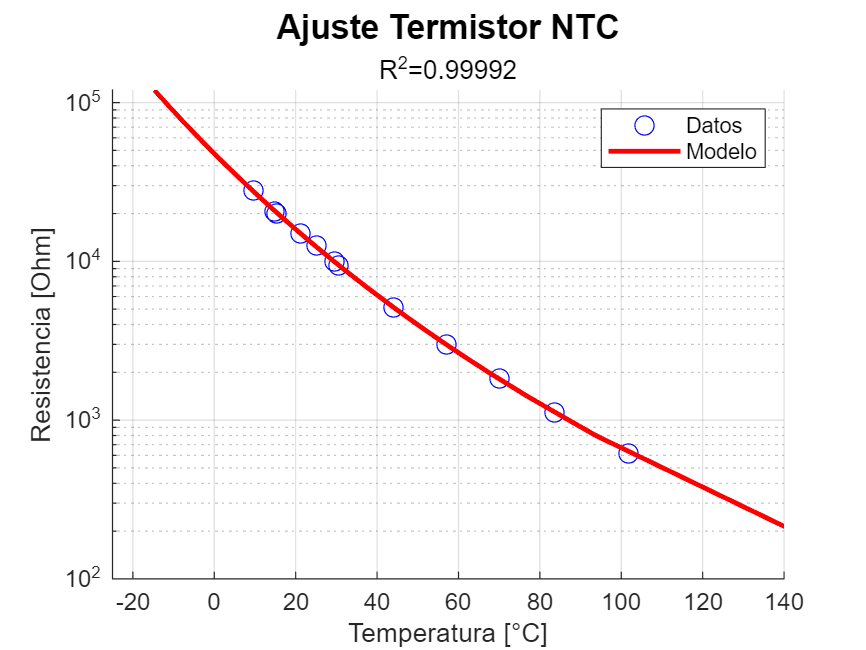



% --- 6. Plotting the Result ---
% The original model function, used to generate the smooth fit line
original_fun = @(z, yData) (z(1) + z(2) * log(yData) + z(3) * log(yData).^3).^-1;

% Create a smooth range for the y-axis (resistance)
% y_plot = linspace(min(yData), max(yData), 100);
y_plot = linspace(2e2, 1.2e5, 200);

% Generate the fitted x-values (temperature)
x_fit_plot = original_fun(z_fit, y_plot);

% Convert temperature (xData) to Celsius for plotting (assuming xData is Kelvin)
xData_C = xData - 273.15;
x_fit_plot_C = x_fit_plot - 273.15;


figure1 = figure('Name','Figure');

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Create semilogy
semilogy(xData_C,yData,'DisplayName','Datos','MarkerSize',8,'Marker','o',...
    'LineStyle','none',...
    'Color',[0 0 1],...
    'ZDataSource','');

% Create semilogy
semilogy(x_fit_plot_C,y_plot,'DisplayName','Modelo','LineWidth',2,...
    'Color',[1 0 0],...
    'ZDataSource','');

xlim([-25 140])

% Labels
ylabel('Resistencia [Ohm]');
xlabel('Temperatura [°C]');
title('Ajuste Termistor NTC', 'FontSize',14);
subtitle('R^2=0.99992')

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[-20 140]);
grid(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'YMinorTick','on','YScale','log');
% Create legend
legend(axes1,'show');

exportgraphics(gcf, 'termistor_ntc_ln.png')



original_fun(z_fit, 10000)-273.15

ans = 29.4235


R_test = 47700;

res = (z_fit(1) + z_fit(2) * log(R_test) + z_fit(3) * log(R_test).^3).^-1 - 273.15

res = 0.0216


$$\left(\begin{array}{c}
0.0011783191977698312651740009115997\\
0.00023216671014162360551537356290197\\
-0.000000014937998019228263835830311100257
\end{array}\right)$$


# Inverse function

R_ntc = 10000;

A_ntc = z_fit(1)

A_ntc = 0.0012

B_ntc = z_fit(2)

B_ntc = 2.3217e-04

C_ntc = z_fit(3)

C_ntc = -1.4938e-08


Temp_c = 29.4248;
Temp = Temp_c + 273.15; 

% Multiples raices en  Cx^3 + Bx + (A - 1/T) = 0
SH_roots = roots([C_ntc, 0, B_ntc, (A_ntc - 1/Temp)]);

% Se descartan las reales
real_roots = SH_roots(imag(SH_roots) == 0);

% Se elije la mas cercana a 0
lnR = real_roots(3); 
R = exp(lnR)

R = 9.9994e+03

N_adc = R_ntc/(R_ntc+R)

N_adc = 0.5000

## Defaults:

pcb hot: 23%

hot chg dsg: 29.5%

cold chg dsg: 64.5%

## Cell range 

Temp = 0;

Temp = Temp + 273.15; 
SH_roots = roots([C_ntc, 0, B_ntc, (A_ntc - 1/Temp)]);
real_roots = SH_roots(imag(SH_roots) == 0);
lnR = real_roots(3); 
R = exp(lnR)

R = 4.7761e+04

N_adc = R_ntc/(R_ntc+R)

N_adc = 0.1731

1-N_adc

ans = 0.8269

(1-N_adc)*1024

ans = 846.7170


% Define your constants and temperature
Temp = 50;

Temp = Temp + 273.15; 
SH_roots = roots([C_ntc, 0, B_ntc, (A_ntc - 1/Temp)]);
real_roots = SH_roots(imag(SH_roots) == 0);
lnR = real_roots(3); 
R = exp(lnR)

R = 3.9850e+03

N_adc = R_ntc/(R_ntc+R)

N_adc = 0.7151

1-N_adc

ans = 0.2849

(1-N_adc)*1024

ans = 291.7873

### **Range:**

{0            50     } °C

{47761     3985} Ohm

{17.31     71.51} %

### inv

{82.69     28.49} %

**847          292**

## PCB range 

% Define your constants and temperature
Temp = 70;

Temp = Temp + 273.15; 
SH_roots = roots([C_ntc, 0, B_ntc, (A_ntc - 1/Temp)]);
real_roots = SH_roots(imag(SH_roots) == 0);
lnR = real_roots(3); 
R = exp(lnR)

R = 1.8152e+03

N_adc = R_ntc/(R_ntc+R)

N_adc = 0.8464

1-N_adc

ans = 0.1536

(1-N_adc)*1024

ans = 157.3213

### **Range:**

70        °C

1815     Ohm

84.64    %

### inv:

15.36%

**157**